# Non-Parametric ANOVA Example

Andrew Brown

GEEN 3853

11/2/2020

## INTRODUCTION

For this non-parametric ANOVA example, we are looking at COVID-19 death rates for different populations based on race.

#### Research Question

To what extent do the COVID-19 death rates differ by race?

## PREP WORKSPACE

clear all
close all
clc

## LOAD THE DATA

We first load the dataset for the death totals.

opts = delimitedTextImportOptions("NumVariables", 12);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Dataasof", "StartWeek", "EndWeek", "State", "Indicator", "NonHispanicWhite", "NonHispanicBlackorAfricanAmerican", "NonHispanicAmericanIndianorAlaskaNative", "NonHispanicAsian", "HispanicorLatino", "Other", "Footnote"];
opts.VariableTypes = ["datetime", "datetime", "datetime", "string", "categorical", "double", "double", "double", "double", "double", "double", "string"];
opts = setvaropts(opts, 1, "InputFormat", "MM/dd/yyyy");
opts = setvaropts(opts, 2, "InputFormat", "MM/dd/yyyy");
opts = setvaropts(opts, 3, "InputFormat", "MM/dd/yyyy");
opts = setvaropts(opts, 12, "WhitespaceRule", "preserve");
opts = setvaropts(opts, [4, 5, 12], "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
raw = readtable("COVID-19_Distribution_of_Deaths_by_Race_and_Hispanic_Origin.csv", opts);

We also need the population estimates for each state.

opts = delimitedTextImportOptions("NumVariables", 151);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["SUMLEV", "REGION", "DIVISION", "STATE", "NAME", "CENSUS2010POP", "ESTIMATESBASE2010", "POPESTIMATE2010", "POPESTIMATE2011", "POPESTIMATE2012", "POPESTIMATE2013", "POPESTIMATE2014", "POPESTIMATE2015", "POPESTIMATE2016", "POPESTIMATE2017", "POPESTIMATE2018", "POPESTIMATE2019", "NPOPCHG_2010", "NPOPCHG_2011", "NPOPCHG_2012", "NPOPCHG_2013", "NPOPCHG_2014", "NPOPCHG_2015", "NPOPCHG_2016", "NPOPCHG_2017", "NPOPCHG_2018", "NPOPCHG_2019", "BIRTHS2010", "BIRTHS2011", "BIRTHS2012", "BIRTHS2013", "BIRTHS2014", "BIRTHS2015", "BIRTHS2016", "BIRTHS2017", "BIRTHS2018", "BIRTHS2019", "DEATHS2010", "DEATHS2011", "DEATHS2012", "DEATHS2013", "DEATHS2014", "DEATHS2015", "DEATHS2016", "DEATHS2017", "DEATHS2018", "DEATHS2019", "NATURALINC2010", "NATURALINC2011", "NATURALINC2012", "NATURALINC2013", "NATURALINC2014", "NATURALINC2015", "NATURALINC2016", "NATURALINC2017", "NATURALINC2018", "NATURALINC2019", "INTERNATIONALMIG2010", "INTERNATIONALMIG2011", "INTERNATIONALMIG2012", "INTERNATIONALMIG2013", "INTERNATIONALMIG2014", "INTERNATIONALMIG2015", "INTERNATIONALMIG2016", "INTERNATIONALMIG2017", "INTERNATIONALMIG2018", "INTERNATIONALMIG2019", "DOMESTICMIG2010", "DOMESTICMIG2011", "DOMESTICMIG2012", "DOMESTICMIG2013", "DOMESTICMIG2014", "DOMESTICMIG2015", "DOMESTICMIG2016", "DOMESTICMIG2017", "DOMESTICMIG2018", "DOMESTICMIG2019", "NETMIG2010", "NETMIG2011", "NETMIG2012", "NETMIG2013", "NETMIG2014", "NETMIG2015", "NETMIG2016", "NETMIG2017", "NETMIG2018", "NETMIG2019", "RESIDUAL2010", "RESIDUAL2011", "RESIDUAL2012", "RESIDUAL2013", "RESIDUAL2014", "RESIDUAL2015", "RESIDUAL2016", "RESIDUAL2017", "RESIDUAL2018", "RESIDUAL2019", "RBIRTH2011", "RBIRTH2012", "RBIRTH2013", "RBIRTH2014", "RBIRTH2015", "RBIRTH2016", "RBIRTH2017", "RBIRTH2018", "RBIRTH2019", "RDEATH2011", "RDEATH2012", "RDEATH2013", "RDEATH2014", "RDEATH2015", "RDEATH2016", "RDEATH2017", "RDEATH2018", "RDEATH2019", "RNATURALINC2011", "RNATURALINC2012", "RNATURALINC2013", "RNATURALINC2014", "RNATURALINC2015", "RNATURALINC2016", "RNATURALINC2017", "RNATURALINC2018", "RNATURALINC2019", "RINTERNATIONALMIG2011", "RINTERNATIONALMIG2012", "RINTERNATIONALMIG2013", "RINTERNATIONALMIG2014", "RINTERNATIONALMIG2015", "RINTERNATIONALMIG2016", "RINTERNATIONALMIG2017", "RINTERNATIONALMIG2018", "RINTERNATIONALMIG2019", "RDOMESTICMIG2011", "RDOMESTICMIG2012", "RDOMESTICMIG2013", "RDOMESTICMIG2014", "RDOMESTICMIG2015", "RDOMESTICMIG2016", "RDOMESTICMIG2017", "RDOMESTICMIG2018", "RDOMESTICMIG2019", "RNETMIG2011", "RNETMIG2012", "RNETMIG2013", "RNETMIG2014", "RNETMIG2015", "RNETMIG2016", "RNETMIG2017", "RNETMIG2018", "RNETMIG2019"];
opts.VariableTypes = ["double", "double", "double", "double", "string", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];
opts = setvaropts(opts, 5, "WhitespaceRule", "preserve");
opts = setvaropts(opts, 5, "EmptyFieldRule", "auto");
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
rawPop = readtable("US_Census_PopulationEst2019-alldata.csv", opts);
rawPop(1:5,:)

ans = 5×151 table
    SUMLEV    REGION    DIVISION    STATE           NAME           CENSUS2010POP    ESTIMATESBASE2010    POPESTIMATE2010    POPESTIMATE2011    POPESTIMATE2012    POPESTIMATE2013    POPESTIMATE2014    POPESTIMATE2015    POPESTIMATE2016    POPESTIMATE2017    POPESTIMATE2018    POPESTIMATE2019    NPOPCHG_2010    NPOPCHG_2011    NPOPCHG_2012    NPOPCHG_2013    NPOPCHG_2014    NPOPCHG_2015    NPOPCHG_2016    NPOPCHG_2017    NPOPCHG_2018    NPOPCHG_2019    BIRTHS2010    BIRTHS2011    

## CLEAN AND SUBSET THE DATA

Ultimately, we need two pieces of information to calculate death rate: 1) the number of deaths for each racial category for each state, and 2) the number of people in that state within each racial category.

In the raw population table, when need to pull out the state name and the population estimates for 2019.

popEst = rawPop(:, ["NAME", "POPESTIMATE2019"]);
popEst.Properties.VariableNames{1} = 'State';

%pull out the individual states
    %Remove Puerto Rico (don't have COVID data)
popEst = popEst(6:end-1,:);

In the COVID database, we need to pull out the state name, death counts, and the population proportions.

covid_row = raw.Indicator == "Count of COVID-19 deaths";
ds_covid = raw(covid_row, 4:end);

pop_row = raw.Indicator == "Unweighted distribution of population (%)";
ds_pop = raw(pop_row, 4:end);
%Take out the US (as a whole) data
ds_pop = ds_pop(2:end,:);
%Take out New York City
temp = ds_pop.State == "New York City";
ds_pop = ds_pop(~temp,:);

%Multiple population percentatages by the overall population to get a
%population count
ds_pop = join(ds_pop, popEst);
%make the percentages a proportion
ds_pop{:, 3:8} = ds_pop{:, 3:8}./100;
%multiply the proportions by the state populations to get the counts of
%people in each racial category
ds_pop{:, 3:8} = ds_pop{:, 3:8}.*ds_pop.POPESTIMATE2019;

%Take US (overall) and New York City out of Covid table
ds_covid = ds_covid(2:end,:);
temp = ds_covid.State == "New York City";
ds_covid = ds_covid(~temp,:);

Now we need to find the death rate for each state, which is the death counts/population counts.  We have two tables that have this data, so we need to divide the covid counts by the population counts in an element-wise fashion.

DR_tab = ds_covid(:,[1,3:8]);
DR_tab{:,2:end} = DR_tab{:,2:end}./ds_pop{:,3:8};

DR = table2array(DR_tab(:,2:end));

%Subset death rates by race
drWhitePeopleX = DR(:,1);
drBlackPeopleX = DR(:,2);
drNativePeopleX = DR(:,3);
drAsianPeopleX = DR(:,4);
drLatinoPeopleX = DR(:,5);
drOtherPeopleX = DR(:,6);

%Omit NaN values
drWhitePeople = zeros(48,1);
drBlackPeople = zeros(39,1);
drNativePeople = zeros(29,1);
drAsianPeople = zeros(41,1);
drLatinoPeople = zeros(43,1);
drOtherPeople = zeros(29,1);

counter = 1;
for i=1:48
    if ~isnan(drWhitePeopleX(i,1))
        drWhitePeople(counter) = drWhitePeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;
for i=1:48
    if ~isnan(drBlackPeopleX(i,1))
        drBlackPeople(counter) = drBlackPeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;
for i=1:48
    if ~isnan(drNativePeopleX(i,1))
        drNativePeople(counter) = drNativePeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;
for i=1:48
    if ~isnan(drAsianPeopleX(i,1))
        drAsianPeople(counter) = drAsianPeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;
for i=1:48
    if ~isnan(drLatinoPeopleX(i,1))
        drLatinoPeople(counter) = drLatinoPeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;
for i=1:48
    if ~isnan(drOtherPeopleX(i,1))
        drOtherPeople(counter) = drOtherPeopleX(i);
        counter = counter + 1;
    end
end
counter = 1;

%Get average death rate for each race in America
avgDRWhitePeople = mean(drWhitePeople);
avgDRBlackPeople = mean(drBlackPeople);
avgDRNativePeople = mean(drNativePeople);
avgDRAsianPeople = mean(drAsianPeople);
avgDRLatinoPeople = mean(drLatinoPeople);
avgDROtherPeople = mean(drOtherPeople);

avgDRarray = [avgDRWhitePeople;avgDRBlackPeople;avgDRNativePeople;avgDRAsianPeople;avgDRLatinoPeople;avgDROtherPeople];
racesArray = categorical({'White','Black','Native','Asian','Latino/Hispanic','Other'});
racesArray = reordercats(racesArray,{'White','Black','Native','Asian','Latino/Hispanic','Other'});
sracesArray = ["White","Black","Native","Asian","Latino/Hispanic","Other"];

%Get data in long format
dataLong = cat(1,drWhitePeople,drBlackPeople,drNativePeople,drAsianPeople,drLatinoPeople,drOtherPeople); %All death rate data in long format
numsLong = cat(1,zeros(48,1),ones(39,1),2*ones(29,1),3*ones(41,1),4*ones(43,1),5*ones(30,1)); %Long format categorical nums


## DESCRIPTIVE STATISTICS - VISUAL

### Histograms

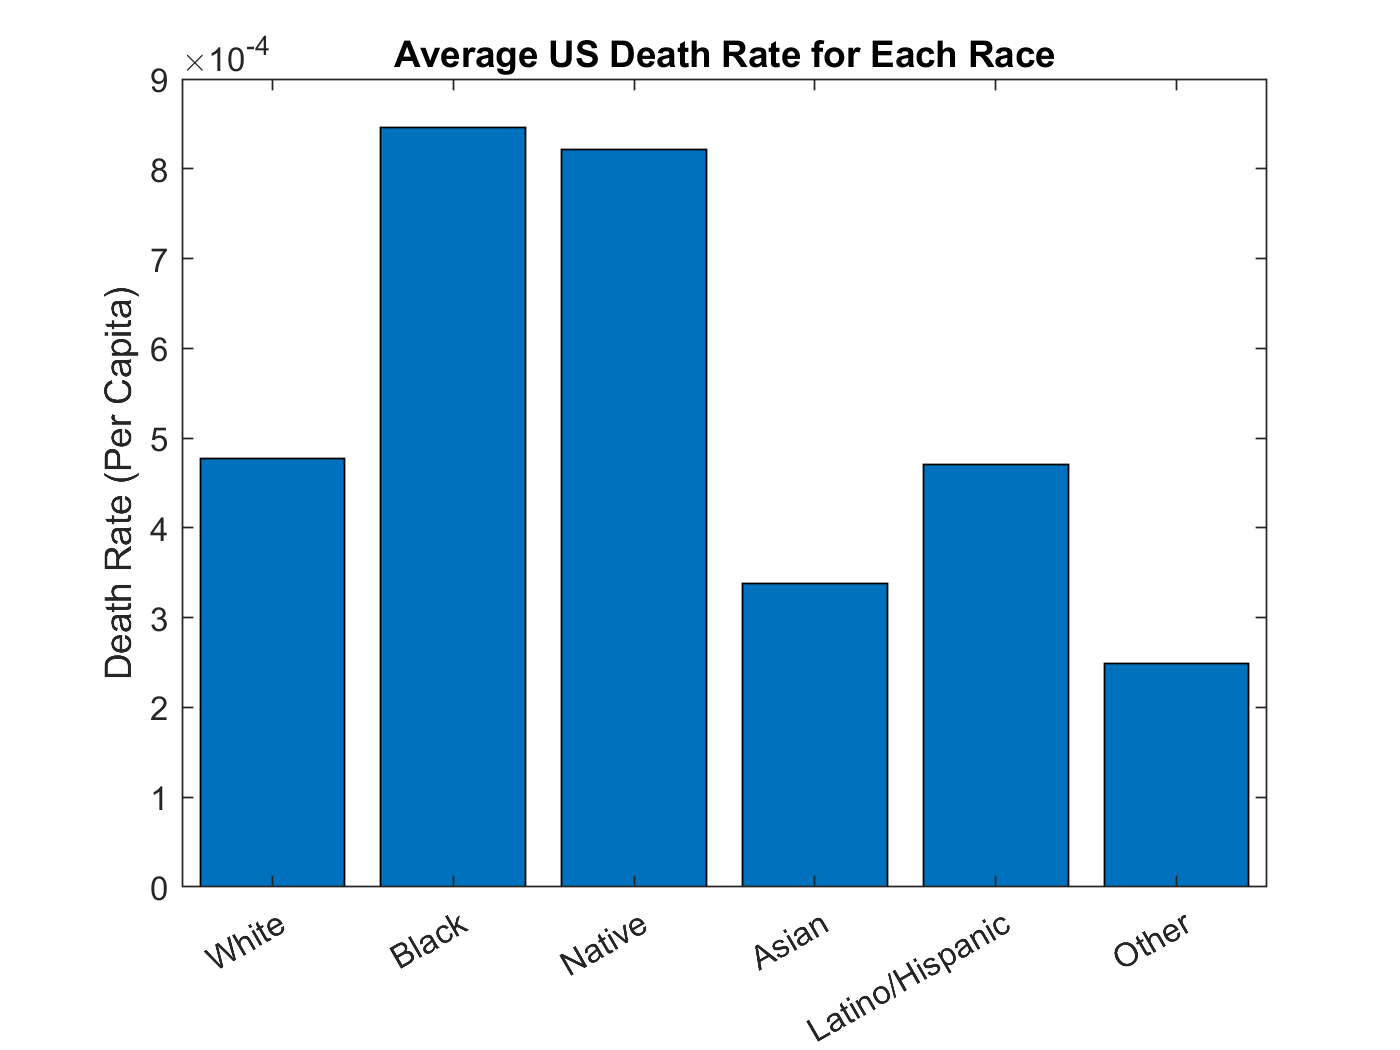

figure
bar(racesArray,avgDRarray);
ylabel("Death Rate (Per Capita)")
title("Average US Death Rate for Each Race")

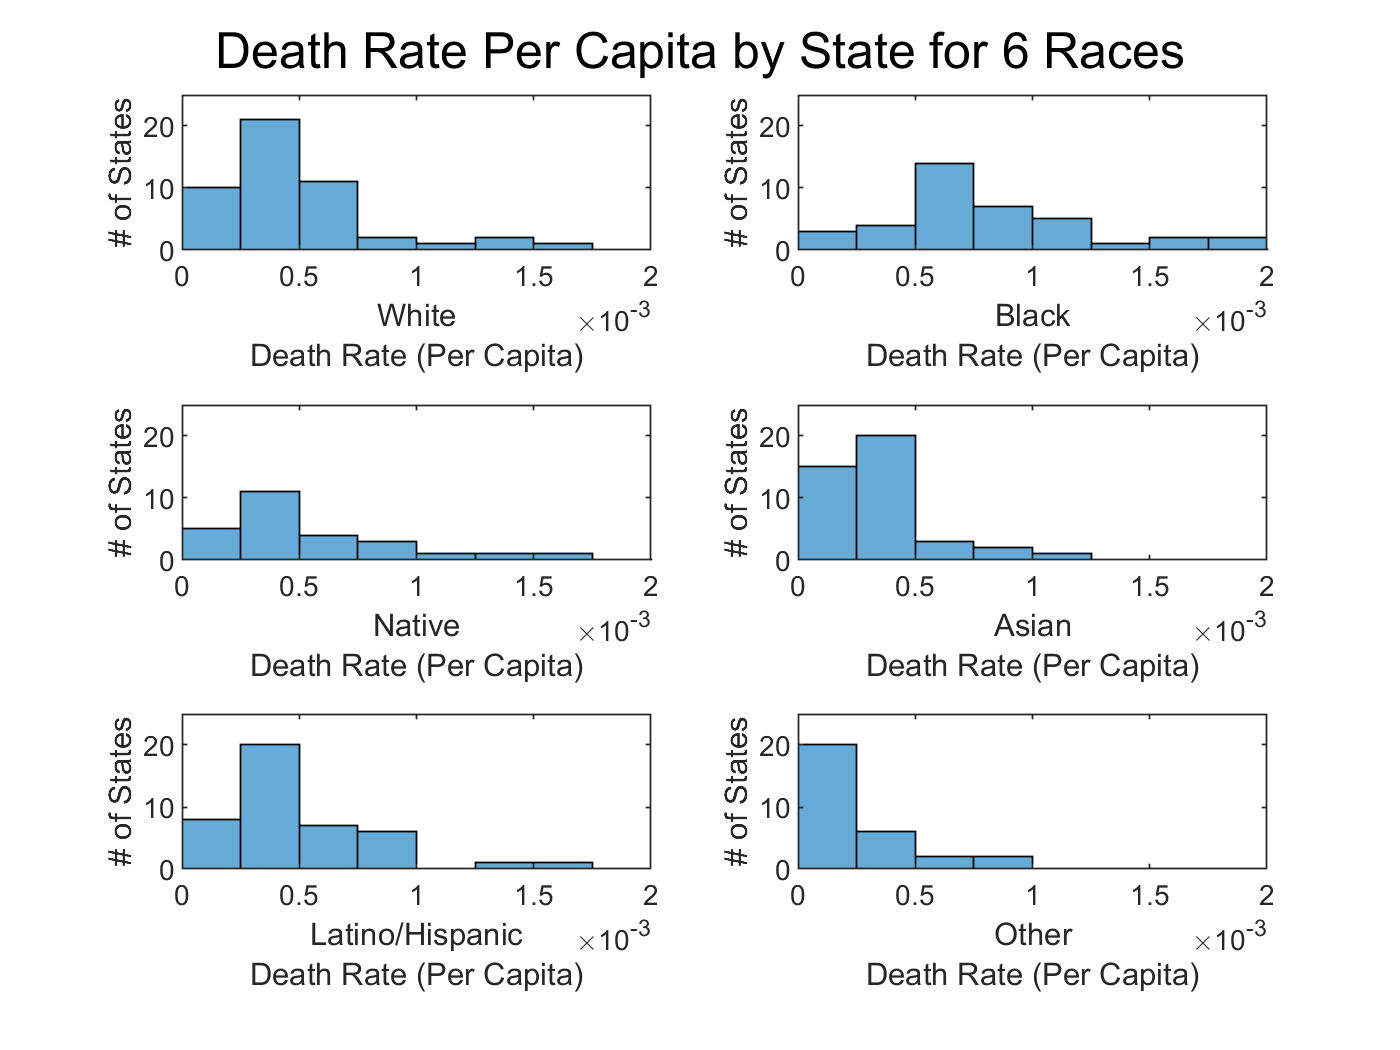

figure
for i=1:6
    subplot(3,2,i)
    histogram(DR(:,i),'BinWidth',0.00025)
    axis([0,20*10^(-4),0,25])
    ylabel("# of States")
    xlabel([sracesArray(i),'Death Rate (Per Capita)'])
end
sgtitle("Death Rate Per Capita by State for 6 Races")

#### Probability Density Function Plots

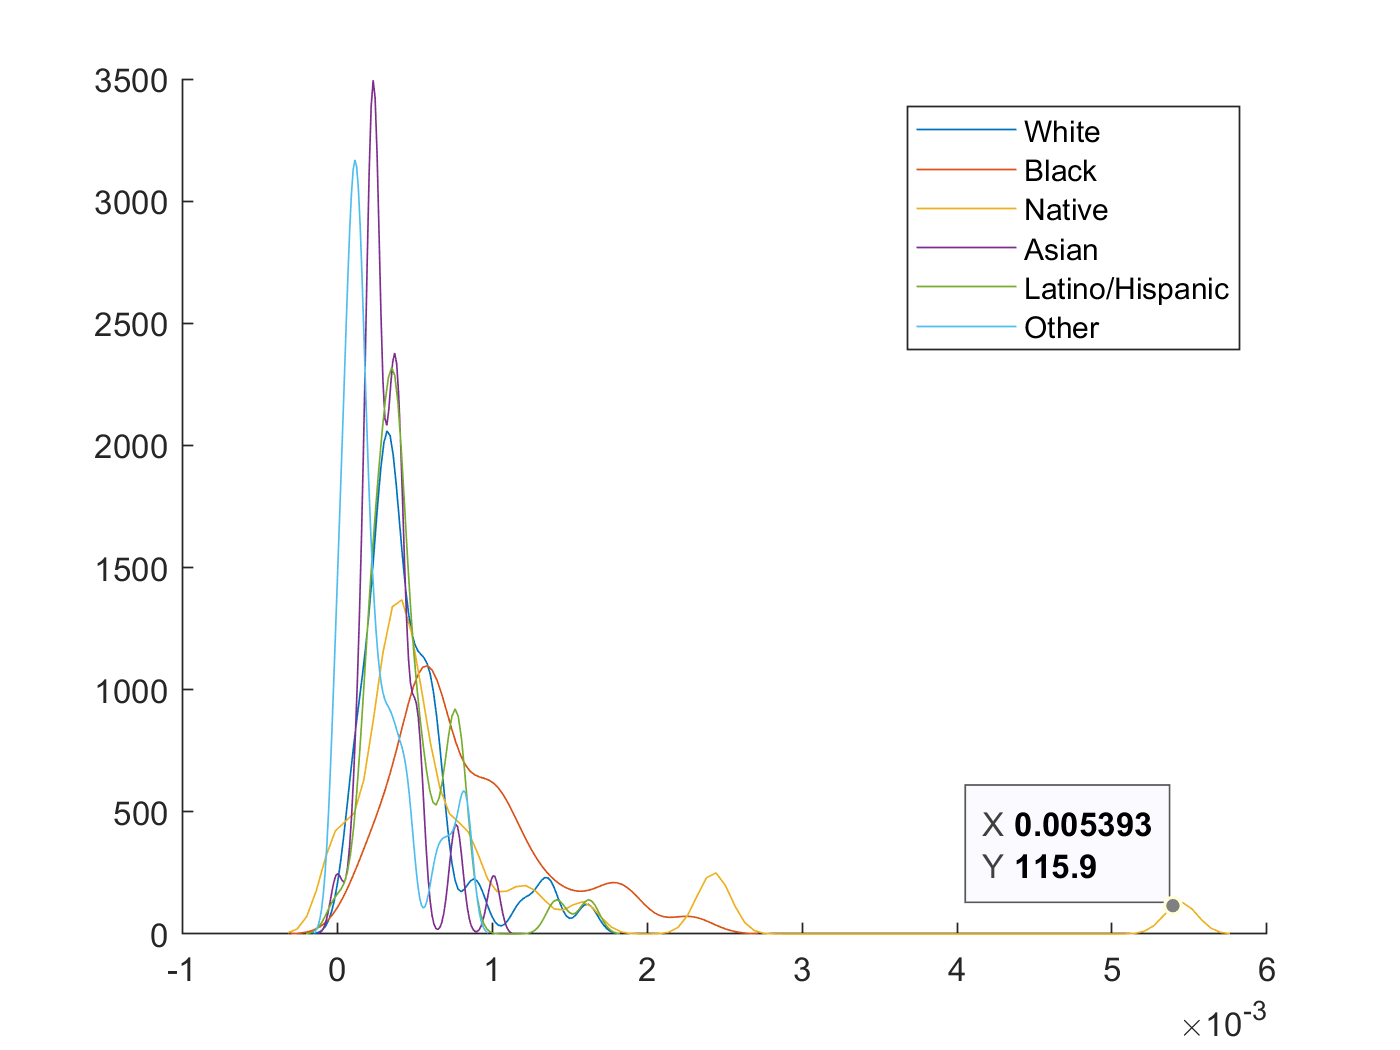

figure
hold on
ksdensity(DR(:,1),'function','pdf','Bandwidth',6.8327*10^(-5)) % Default Bandwidth = 1.0249e-04
ksdensity(DR(:,2),'function','pdf','Bandwidth',1.4757*10^(-4)) % Default Bandwidth = 2.2136e-04
ksdensity(DR(:,3),'function','pdf','Bandwidth',1.0611*10^(-4)) % Default Bandwidth = 1.5917e-04
ksdensity(DR(:,4),'function','pdf','Bandwidth',4.0530*10^(-5)) % Default Bandwidth = 6.0795e-05
ksdensity(DR(:,5),'function','pdf','Bandwidth',6.6637*10^(-5)) % Default Bandwidth = 9.9955e-05
ksdensity(DR(:,6),'function','pdf','Bandwidth',4.8127*10^(-5)) % Default Bandwidth = 7.2190e-05
legend(sracesArray)
hold off

**Take Aways: **

From the histograms and PDF plots, it isquite difficult to tell exactly what is going on. However, it seems that the White, Asian, Latino, and Other populations have a smaller average death rate than that of the Black and Native populations. Boxplots may show this more clearly.

## Boxplots

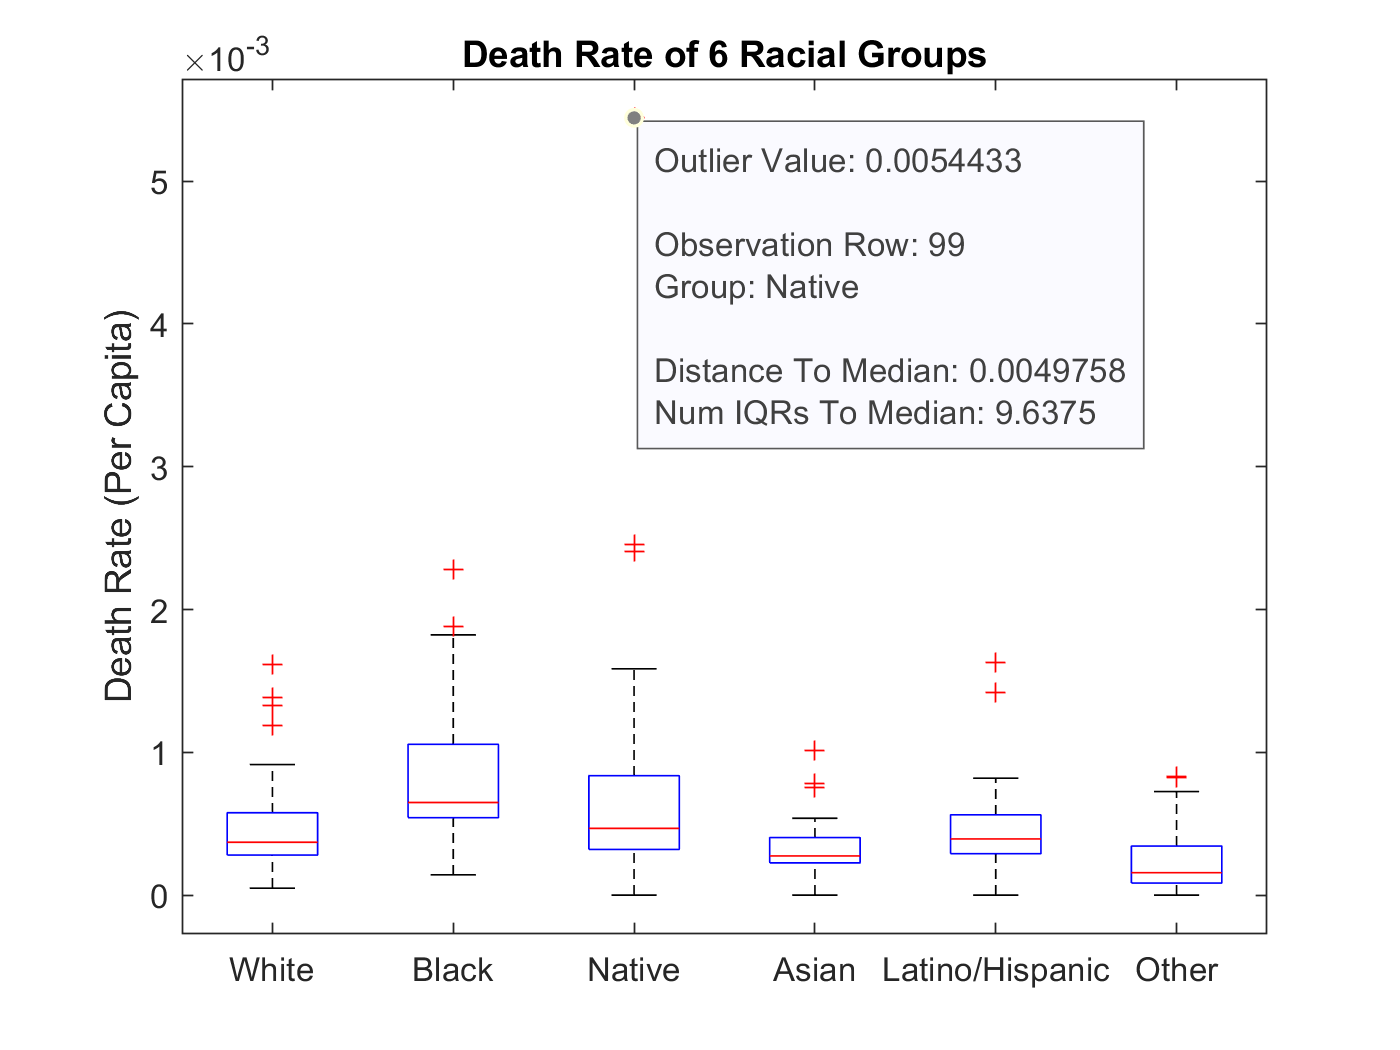

figure
boxplot(dataLong,numsLong,"Labels",["White","Black","Native","Asian","Latino/Hispanic","Other"])
ylabel ('Death Rate (Per Capita)')
title('Death Rate of 6 Racial Groups')
hold off

**Take Aways: **

From the Boxplot, quite a few different things become clear. The populations in ascending order of average death rate are as follows: Other, Asian, White, Latino/Hispanic, Native, Black. In addition, the Native and Black populations have clearly larger variances than the rest of the populations skewing upwards.

## DESCRIPTIVE STATISTICS - NUMERIC

## Univariate

%Set up a results table
tWhite = table();

tWhite.Mean = mean(drWhitePeople)';
tWhite.SD = std(drWhitePeople)';
tWhite.Med = median(drWhitePeople)';
tWhite.Max = max(drWhitePeople)';
tWhite.Min = min(drWhitePeople)';
tWhite.IQR = iqr(drWhitePeople)';

tBlack = table();

tBlack.Mean = mean(drBlackPeople)';
tBlack.SD = std(drBlackPeople)';
tBlack.Med = median(drBlackPeople)';
tBlack.Max = max(drBlackPeople)';
tBlack.Min = min(drBlackPeople)';
tBlack.IQR = iqr(drBlackPeople)';

tNative = table();

tNative.Mean = mean(drNativePeople)';
tNative.SD = std(drNativePeople)';
tNative.Med = median(drNativePeople)';
tNative.Max = max(drNativePeople)';
tNative.Min = min(drNativePeople)';
tNative.IQR = iqr(drNativePeople)';

tAsian = table();

tAsian.Mean = mean(drAsianPeople)';
tAsian.SD = std(drAsianPeople)';
tAsian.Med = median(drAsianPeople)';
tAsian.Max = max(drAsianPeople)';
tAsian.Min = min(drAsianPeople)';
tAsian.IQR = iqr(drAsianPeople)';

tLatino = table();

tLatino.Mean = mean(drLatinoPeople)';
tLatino.SD = std(drLatinoPeople)';
tLatino.Med = median(drLatinoPeople)';
tLatino.Max = max(drLatinoPeople)';
tLatino.Min = min(drLatinoPeople)';
tLatino.IQR = iqr(drLatinoPeople)';

tOther = table();

tOther.Mean = mean(drOtherPeople)';
tOther.SD = std(drOtherPeople)';
tOther.Med = median(drOtherPeople)';
tOther.Max = max(drOtherPeople)';
tOther.Min = min(drOtherPeople)';
tOther.IQR = iqr(drOtherPeople)';

ds = vertcat(tWhite,tBlack,tNative,tAsian,tLatino,tOther);
ds.Properties.RowNames = sracesArray;
ds

ds = 6×6 table
                          Mean           SD           Med           Max           Min           IQR    
                       __________    __________    __________    __________    __________    __________

    White              0.00047706    0.00033498     0.0003705     0.0016139    4.8821e-05    0.00029662
    Black              0.00084651    0.00049768    0.00064884      0.002277    0.00014226    0.00051362
    Native             0.00082201     0.0010782    0.00046747     0.0054433             0    0.00051629
    Asian              0.00033855    0.00018836    0.00027449      0.001011             0    0.00017731
    Latino/Hispanic    0.00047052    0.00030648    0.00039331     0.001

**Take Aways: **

The descriptive univariate statistics confirm numerically our hypotheses from the visual statistics that there is a clear difference in means and standard deviation of the populations with the death rates in ascending order being Other, Asian, White, Latino/Hispanic, Native, Black and the Black and Native populations haveing the largest standard deviations. In addition, the Black and Native populaitons the highest medians and maxes. 

### Bivariate

The most common bivariate statistic that we will utilize is the correlation coefficient.

This doesn't make sense to compute for this data/problem.

# INFERENTIAL STATISTICS

Our ultimate goal is to test the difference in means.  However, to do that, we need to first test the normality of the groups.  We also need to know if the groups have equal or unequal variance so that we know what t-test to use in our test of location.

## TEST OF NORMALITY

For a two-sample, independent test, we need to test the normality of each group.

Underlying Assumptions of the Test :

- The data are continuous.

- The data are from a sample that was randomly drawn from a process/population.

Method: Anderson-Darling and Normality Plot

Step 1 : (Note that a non-directional test is assumed.)

H0 :$\gamma$_3 = 0 and $\gamma$_4 = 0 for all groups

H1 : $\gamma$_3 $\not=$ 0 and $\gamma$_4 $\not=$ 0 for some/all groups

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make

alpha1 = 0.05

alpha1 = 0.0500

Step 3 : We will use the AD test statistic.

Step 4 : We will use the AD RSD

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    Quantitative: Reject H0 if any p-value < $\alpha$ 

Step 6 : Calculations

### Normality Plot & Anderson-Darling Statistic

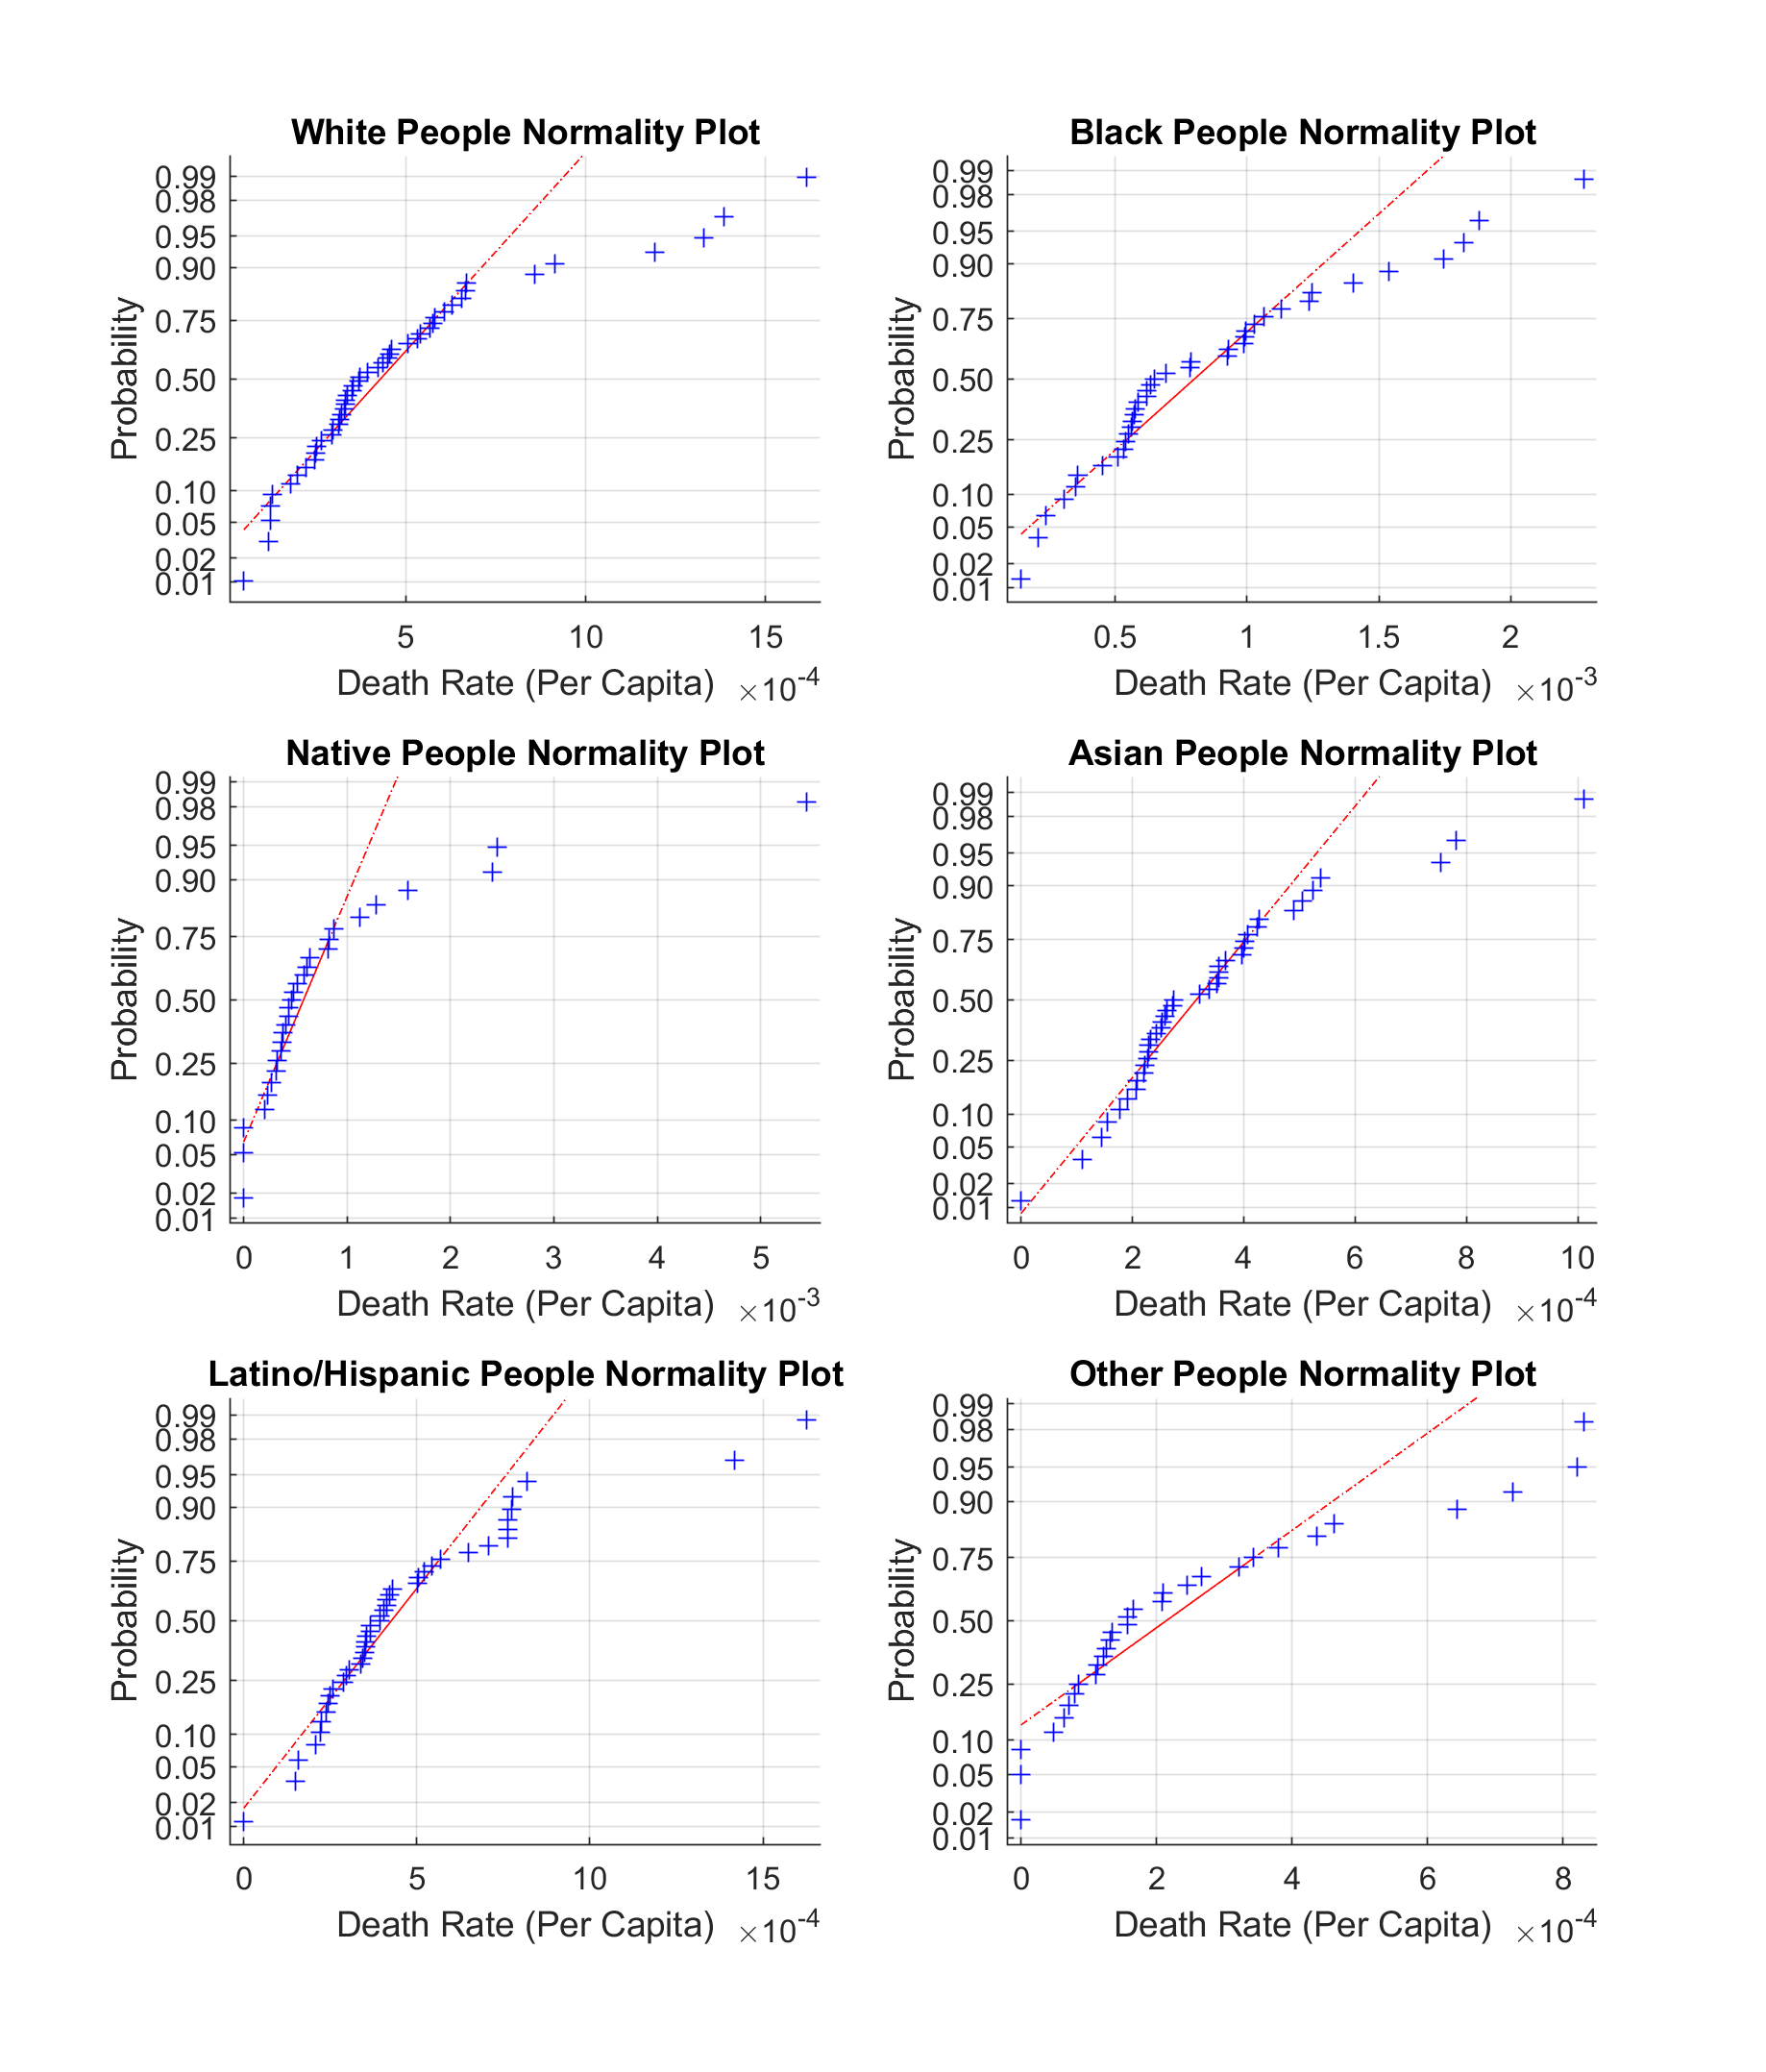

figure = figure('Position', [100, 100, 1024, 1200]);
subplot(3,2,1)
normplot(drWhitePeople) %quanlitative check
title('White People Normality Plot')
xlabel('Death Rate (Per Capita)')

subplot(3,2,2)
normplot(drBlackPeople)
title('Black People Normality Plot')
xlabel('Death Rate (Per Capita)')

subplot(3,2,3)
normplot(drNativePeople)
title('Native People Normality Plot')
xlabel('Death Rate (Per Capita)')

subplot(3,2,4)
normplot(drAsianPeople)
title('Asian People Normality Plot')
xlabel('Death Rate (Per Capita)')

subplot(3,2,5)
normplot(drLatinoPeople)
title('Latino/Hispanic People Normality Plot')
xlabel('Death Rate (Per Capita)')

subplot(3,2,6)
normplot(drOtherPeople)
title('Other People Normality Plot')
xlabel('Death Rate (Per Capita)')

**Take Aways**

This normality plot shows that all 6 populations roughly follow a nonlinear regression line. It is likely one or more populations will not be normal when we run our AD Test.

%anderson-darling test for normality
% Ho: sample is normal, H1: sample is non-normal
[h1_norm(1),p1_norm(1), AD_stat(1), cv_norm(1)] = adtest(drWhitePeople);

[h1_norm(2),p1_norm(2), AD_stat(2), cv_norm(2)] = adtest(drBlackPeople);
[h1_norm(3),p1_norm(3), AD_stat(3), cv_norm(3)] = adtest(drNativePeople);

[h1_norm(4),p1_norm(4), AD_stat(4), cv_norm(4)] = adtest(drAsianPeople);

[h1_norm(5),p1_norm(5), AD_stat(5), cv_norm(5)] = adtest(drLatinoPeople);

[h1_norm(6),p1_norm(6), AD_stat(6), cv_norm(6)] = adtest(drOtherPeople);

h1_norm

h1_norm = 1×6 logical array
   1   1   1   1   1   1


p1_norm

p1_norm =     0.0005    0.0030    0.0005    0.0005    0.0005    0.0005


### Decision

Step 7a) Decision : **Reject H0 for all 6 groups**

7b) p = see above

7c) We have sufficient statistical evidence to infer that all 6 of the populations from which these data were randomly sampled may NOT be approximated by the Normal distribution. 

Based on n = (see below), the A-D tests are appropriate for this analysis.

n = [size(drWhitePeople,1) size(drBlackPeople,1) size(drNativePeople,1) size(drAsianPeople,1) size(drLatinoPeople,1) size(drOtherPeople,1)]

n =     48    39    29    41    43    30


Multiple sample size variables are appropriate for this problem because all groups have different sample sizes.

**Take Aways:**

All samples cannot be approximated by normal distribution. Non-parametric strategies must be used for further statistical analysis.

## TEST OF DIFFERENCE

For 6 sample, independent, and non-parametric data, we have NO assumptions.

We only know the following:

- Random, Representative samples.

- All samples come from populations having the same continuous distribution.

- All observations are mutually independent.

Method: Kruskal-Wallis Rank ANOVA

Step 1 : (Note that a non-directional test is assumed.)

H0 : All populations are equal 

H1: All populations are not equal (at least two populations are statistically different in some way)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make is 5%.

Step 3 : We will use the H statistic.

Step 4 : We do not have the information for the RSD or degrees of freedom because the data is non-parametric.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if the p-value < alpha

Step 6: Calculations

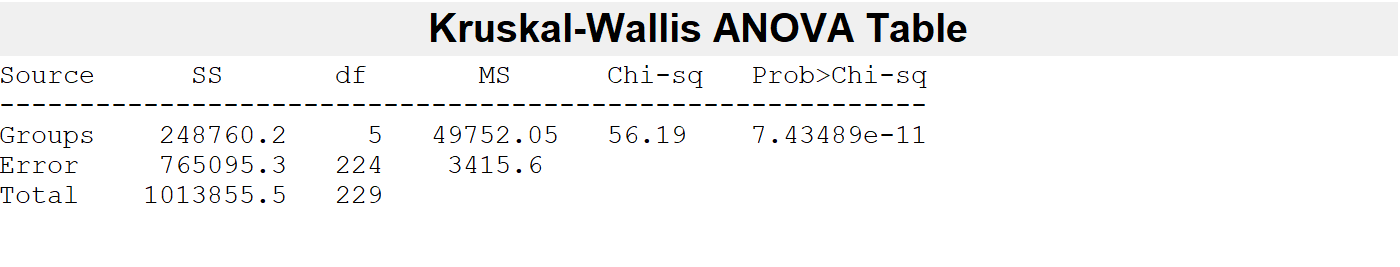

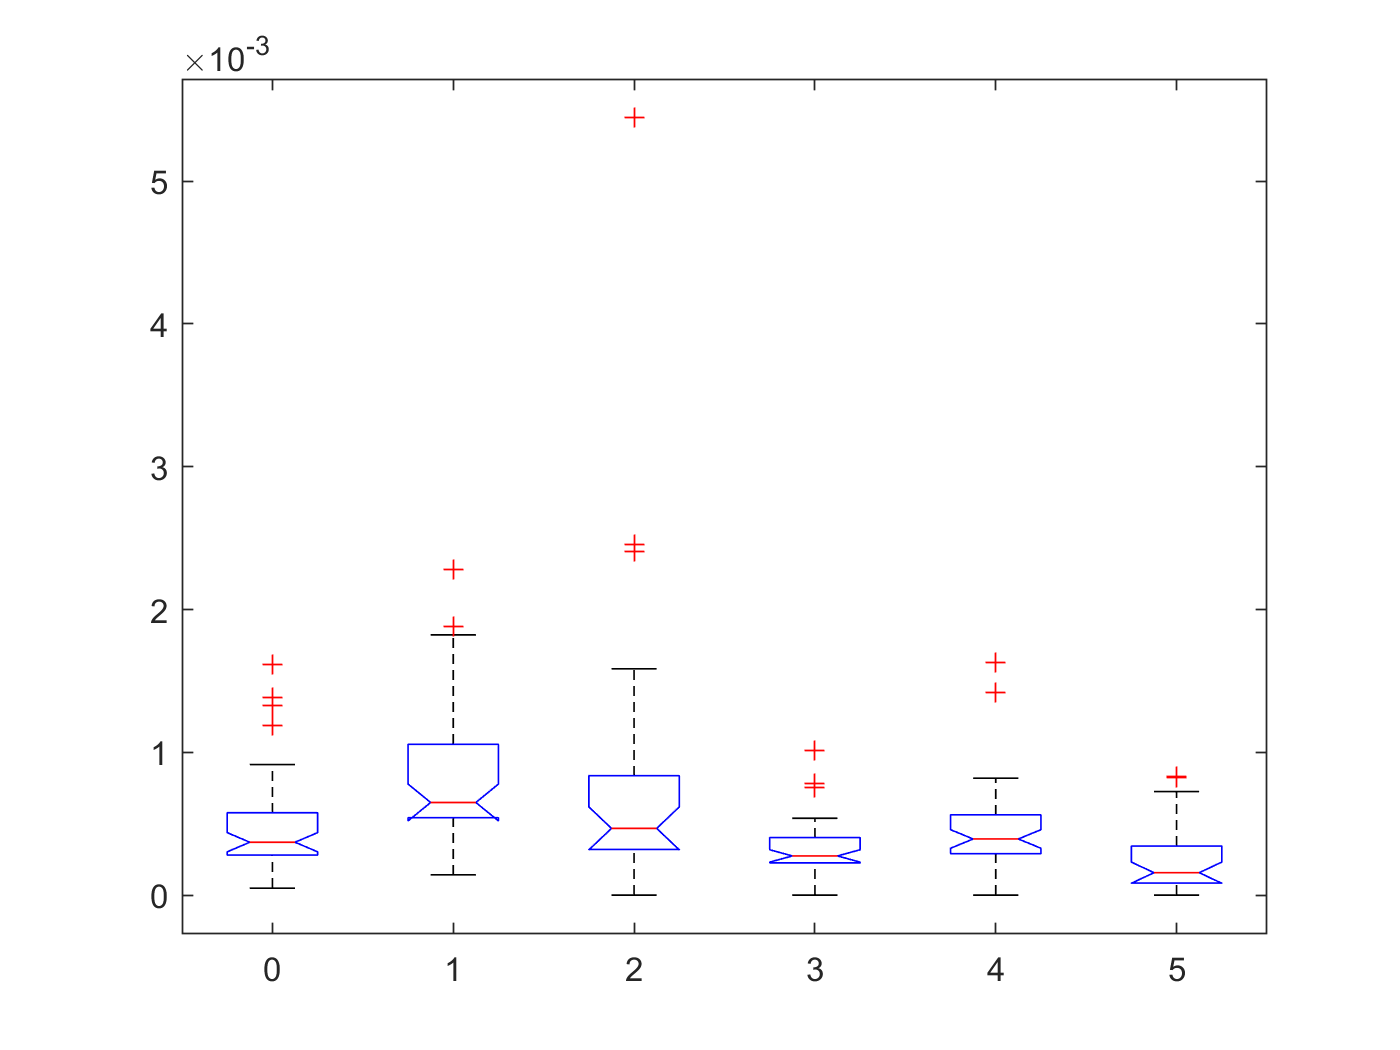

p_ANOVA = 7.4349e-11

tbl_ANOVA = 4×6 cell array
    {'Source'}    {'SS'        }    {'df' }    {'MS'        }    {'Chi-sq'  }    {'Prob>Chi-sq'}
    {'Groups'}    {[2.4876e+05]}    {[  5]}    {[4.9752e+04]}    {[ 56.1876]}    {[ 7.4349e-11]}
    {'Error' }    {[7.6510e+05]}    {[224]}    {[3.4156e+03]}    {0×0 double}    {0×0 double   }
    {'Total' }    {[1.0139e+06]}    {[229]}    {0×0 double  }    {0×0 double}    {0×0 double   }


stats_ANOVA = struct with fields:
       gnames: {6×1 cell}
            n: [48 39 29 41 43 30]
       source: 'kruskalwallis'
    meanranks: [115.0833 170.2308 135.5345 88.1829 116.9884 60.8500]
         sumt: 504


[p_ANOVA,tbl_ANOVA,stats_ANOVA] = kruskalwallis(dataLong,numsLong)

### Decision

Step 7a) Decision : **Reject H0**

7b) p < .001 (p less than alpha)

7c) We have sufficient statistical evidence to infer that at least one population is statistically different from at least one other population. Post-Hoc Analysis will be necessary.

7d) Appropriate Point Estimates

ds

ds = 6×6 table
                          Mean           SD           Med           Max           Min           IQR    
                       __________    __________    __________    __________    __________    __________

    White              0.00047706    0.00033498     0.0003705     0.0016139    4.8821e-05    0.00029662
    Black              0.00084651    0.00049768    0.00064884      0.002277    0.00014226    0.00051362
    Native             0.00082201     0.0010782    0.00046747     0.0054433             0    0.00051629
    Asian              0.00033855    0.00018836    0.00027449      0.001011             0    0.00017731
    Latino/Hispanic    0.00047052    0.00030648    0.00039331     0.001

**Take Aways:** 

From our Kruskal-Wallis ANOVA, we know that some populations are statistically different, however, we do not have an indication of which ones are different or how they are different (location? shape? spread?). In the next section we will discuss which population differ and how the populations differ.

## Post-Hoc Analysis

We will need to use multiple Mann-Whitney U tests along with a Bonferroni in order to figure out where our differences are.

#### Bonferroni

alpha1_PC = alpha1/15

alpha1_PC = 0.0033

#### Mann-Whitney U Tests

For 2 sample, independent, and non-parametric populations, we have NO assumptions.

We only know the following:

- Random, Representative samples.

- All samples come from populations having the same continuous distribution.

- All observations are mutually independent.

Method: 15 Separate Mann-Whitney U Tests

Step 1 : (Note that a non-directional test is assumed.)

H0 : All populations are equal 

H1: All populations are not equal (at least two populations are statistically different in some way)

Step 2: Alpha level; i.e., significance level, or how much Type I error you are willing to make is 5%.

Step 3 : We will use the H statistic.

Step 4 : We do not have the information for the RSD or degrees of freedom because the data is non-parametric.

Step 5 : State the Critical Value for Rejecting the Null Hypothesis

    We will reject the null if the p-value < alpha

Step 6: Calculations

[p_MWU(1),h_MWU(1),stats_MWU(1)] = ranksum(drWhitePeople,drBlackPeople,"alpha",alpha1_PC);
[p_MWU(2),h_MWU(2),stats_MWU(2)] = ranksum(drWhitePeople,drNativePeople,"alpha",alpha1_PC);
[p_MWU(3),h_MWU(3),stats_MWU(3)] = ranksum(drWhitePeople,drAsianPeople,"alpha",alpha1_PC);
[p_MWU(4),h_MWU(4),stats_MWU(4)] = ranksum(drWhitePeople,drLatinoPeople,"alpha",alpha1_PC);
[p_MWU(5),h_MWU(5),stats_MWU(5)] = ranksum(drWhitePeople,drOtherPeople,"alpha",alpha1_PC);
[p_MWU(6),h_MWU(6),stats_MWU(6)] = ranksum(drBlackPeople,drNativePeople,"alpha",alpha1_PC);
[p_MWU(7),h_MWU(7),stats_MWU(7)] = ranksum(drBlackPeople,drAsianPeople,"alpha",alpha1_PC);
[p_MWU(8),h_MWU(8),stats_MWU(8)] = ranksum(drBlackPeople,drLatinoPeople,"alpha",alpha1_PC);
[p_MWU(9),h_MWU(9),stats_MWU(9)] = ranksum(drBlackPeople,drOtherPeople,"alpha",alpha1_PC);
[p_MWU(10),h_MWU(10),stats_MWU(10)] = ranksum(drNativePeople,drAsianPeople,"alpha",alpha1_PC);
[p_MWU(11),h_MWU(11),stats_MWU(11)] = ranksum(drNativePeople,drLatinoPeople,"alpha",alpha1_PC);
[p_MWU(12),h_MWU(12),stats_MWU(12)] = ranksum(drNativePeople,drOtherPeople,"alpha",alpha1_PC);
[p_MWU(13),h_MWU(13),stats_MWU(13)] = ranksum(drAsianPeople,drLatinoPeople,"alpha",alpha1_PC);
[p_MWU(14),h_MWU(14),stats_MWU(14)] = ranksum(drAsianPeople,drOtherPeople,"alpha",alpha1_PC);
[p_MWU(15),h_MWU(15),stats_MWU(15)] = ranksum(drLatinoPeople,drOtherPeople,"alpha",alpha1_PC);

p_MWU

p_MWU =     0.0000    0.1801    0.0334    0.8332    0.0002    0.0486    0.0000    0.0000    0.0000    0.0026    0.1528    0.0004    0.0188    0.0052    0.0001


h_MWU

h_MWU = 1×15 logical array
   1   0   0   0   1   0   1   1   1   1   0   1   0   0   1


### Decision

Step 7a) Decision : **Reject H0 for 8/15 tests**

7b) p < 0.0033 (p less than alpha) for 8 tests

7c) We have sufficient statistical evidence to infer that the following pairs of populations are statistically different in some way.

        White:Black         Black:Asian        Native:Asian        Latino:Other

        White:Other         Black:Latino       Native:Other

                                    Black:Other

7d) Appropriate Point Estimates

ds

ds = 6×6 table
                          Mean           SD           Med           Max           Min           IQR    
                       __________    __________    __________    __________    __________    __________

    White              0.00047706    0.00033498     0.0003705     0.0016139    4.8821e-05    0.00029662
    Black              0.00084651    0.00049768    0.00064884      0.002277    0.00014226    0.00051362
    Native             0.00082201     0.0010782    0.00046747     0.0054433             0    0.00051629
    Asian              0.00033855    0.00018836    0.00027449      0.001011             0    0.00017731
    Latino/Hispanic    0.00047052    0.00030648    0.00039331     0.001

**Take Aways:**

There are 4 main takeaways from this data:

- The Black population is statistically different from all other populations except the Native population.

- The White population is statistically different from only the Black and Other populations.

- The Native population is statistically different from only the Asian and Other populations.

- The Latino population is statistically different from only the Black and Other populations.

## Discussion

In this discussion, the results, including the visual statistics, descriptive numerical statistics, and inferrential statistics, for each of the 6 racial groups will be discussed in ascending order of average death rate.

The Other population was found to have a statistically different death rate than every other population except for the Asian population. Seeing as their mean is considerably lower than all other populations we can conclude that the Other population is doing really well compared most other populations.

The Asian population was found to have a statistically different death rate than only the Black and Native populations. Seeing that the average death rate is about 1/3 those of the Black and Native populations, we can conclude that the Asian population is generally significantly less effected by COVID-19 than both the Black and Native populations.

The White population was found to have a statistically different death rate than only the Other and Black populations. Seeing that the Black and Other populations populate the two extremes of the population mean death rates, we can conclude that the White population is right in the middle with regards to how much they are affected by COVID-19, being significantly different from both the most well-off population and the worst-off population.

The Latino population was found to have a statistically different death rate than only the Other and Black populations. Seeing that the Black and Other populations populate the two extremes of the population mean death rates, we can conclude that the Latino population is right in the middle (along with the White population) with regards to how much they are affected by COVID-19, being significantly different from both the most well-off population and the worst-off population.

The Black population was found to have a statistically different death rate than all other populations except for the Native popultion. Seeing that is has a much larger average death rate than all of these populations (doubling or trippling them in magnitude) it is clear that the Black population is dramatically affected by COVID-19 compared to most other populations.

The Native population was found to have a statstically different rate than only the Asian and Other populations. Seeing that has the largest average death rate, we can conclude that is is one of the populations worst affected by COVID-19.

## How does each population compare to non-hispanic white people?

whitePeopleCompared = zeros(6,1);
for i=1:6
    whitePeopleCompared(i) = avgDRarray(i)/avgDRWhitePeople;
end
whitePeopleCompared;

**Take Aways:**

The Black population has a death rate about 1.77x that of the White population.

The Native population has a death rate about 1.72x that of the White population.

The Asian population has a death rate about 0.71x that of the White population.

The Latino population has a death rate about 0.99x that of the White population.

The Other population has a death rate about 0.52x that of the White population.

## Conclusion

From all of our data, we can approximately group our racial groups into 3 subgroups: Most Affected by COVID-19 (Black and Native Populations), Middle Affected by COVID-19 (Latino and White populations), and Least Affected by COVID-19 (Asian and Other populations). In addition, those populations most affected by COVID-19 have the two highest variances of all the populations, skewing upward, showing that many Black and Native communities around the US are struggling with incredibly high death rates compared to all other communities in the US. While this data does not link these dramatic differences to any particular statistic, it is clear there are systemic issues in the US that are leading to much of the death from this pandemic being put onto these specifc historically oppressed comunities.